## Cepstral 26 Features - Cubic SVM - Monte Carlo Simulations

This live script runs many iterations of randomly sampling from a set of held out signal and contamination files to evaluate the performance of many Cubic SVM models with varying hyperparameters. The goal of this simulation is to establish which settings for both the Ceptral 26 feature set and Cubic SVM model perform the best at the task of identifying contaminated audio. Analysis will be done outside of this live script.

See the following links for more details about Support Vector Machines (SVM) in Matlab:

    [https://www.mathworks.com/help/stats/support-vector-machines-for-binary-classification.html](https://www.mathworks.com/help/stats/support-vector-machines-for-binary-classification.html)

    [https://www.mathworks.com/help/stats/fitcsvm.html](https://www.mathworks.com/help/stats/fitcsvm.html) 

#### Script Setup

% Find base directory
basedir = fileparts(pwd);

% Set data directory
datadir = fullfile(basedir,"data","DataExamplesv2");

% File name for Monte Carlo results
mcfolder = fullfile(basedir,"data","Models");
mcfileName = "Cepstral26CubicSvmSim";
csvfileName = "Cepstral26CubicSvmSim.csv";

#### Settings and Configuration

% Number of Monte Carlo iterations
% Use a small number to make sure everything runs without error, then
% change to a large number for the Monte Carlo simulation
nruns = 100;    % for debugging
% nruns = 1000000;  % for Monte Carlo simulation

% Percent of the data to hold out for simulation
percentHeldOut = 0.4;

% Potential block lengths (seconds)
blockLengths = [1 2 4 8];

% Signal-to-Noise Ratio
signalToNoiseRatios = [6 10 14 18];

#### Results Table Setup

% Initialize table for Monte Carlo results
varNames = ["BlockLength","SignalFile","SignalStartIndx","ContaminatedTrue","FracBlockContaminated","ContaminationStartIndx", ... 
            "ContaminationFile","ContaminationIndx","SNRdB","ContaminatedPred"];
varTypes = ["double","string","double","logical","double","double", ... 
            "string","double","double","logical"];
            
nvars = length(varNames);

tmcoutput = table('Size',[nruns nvars],'VariableTypes',varTypes,'VariableNames',varNames);

#### Data Setup

% Subset signal and contamination sets
rng(42);
fileDescripts = readtable(fullfile(datadir,"FileDescriptions.xlsx"),'TextType','string');
fileDescripts.AircraftPresent = fileDescripts.AircraftPresent == "Y";
fileDescripts.Contaminated = fileDescripts.Contaminated == "Y";

contaminationFiles = fileDescripts.FileName(fileDescripts.Contaminated);
signalFiles = fileDescripts.FileName(~fileDescripts.Contaminated);

% Destinate contamination files to use
heldOutContaminationFiles = datasample(contaminationFiles,floor(length(contaminationFiles)*percentHeldOut),"Replace",false);
primaryContaminationFiles = setdiff(contaminationFiles, heldOutContaminationFiles);

% Destinate signal files to use
heldOutSignalFiles = datasample(signalFiles,floor(length(signalFiles)*percentHeldOut),"Replace",false);
primarySignalFiles = setdiff(signalFiles, heldOutSignalFiles);

nsignals = length(heldOutSignalFiles);
ncontimations = length(heldOutContaminationFiles);

#### 2s - SNR 6 - Example

% Load pre-generated feature set
load('E:\UW\Project\EnvNoiseDetector\data\Features\FeaturesSNR6Cepstral26features.mat')

% Split xfeatures into train and validation data sets
rng(12354)
randrows = randperm(height(xfeatures));
audioTrain = xfeatures(randrows(1:0.8*height(xfeatures)), :);

audioValidation = xfeatures(randrows(0.6*height(xfeatures)+1:end), :);

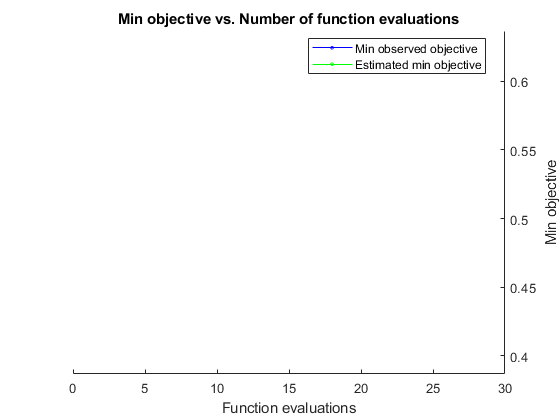

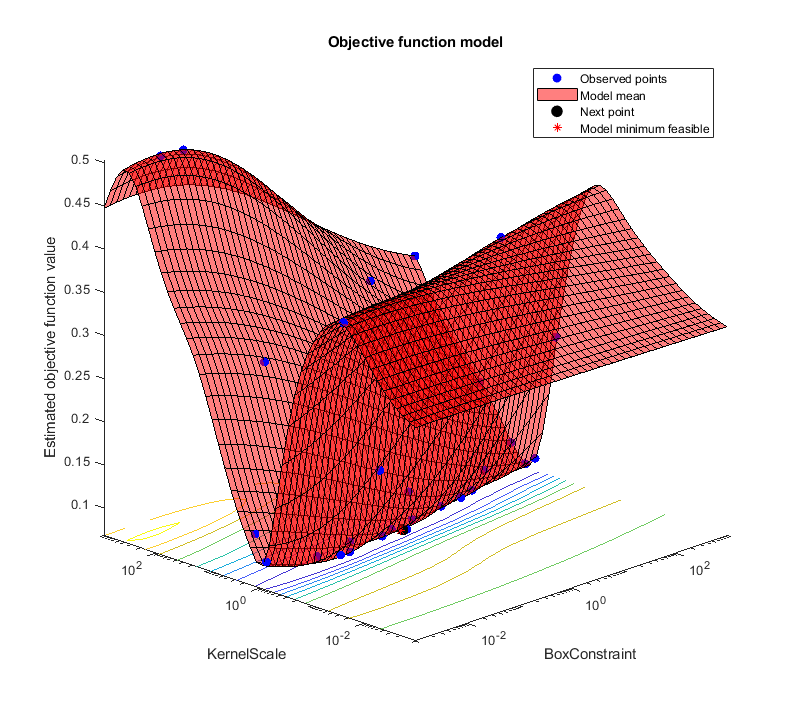

Performing function evaluation on point:                                        48.717 |       361.77 |
Time to select the next point: 0.11819
Time to fit the model(s): 0.052418
|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.27646 |      2.9565 |     0.27646 |     0.27646 |       48.717 |       361.77 |
Performing function evaluation on point:                                        0.1378 |      0.67489 |
Time to select the next point: 0.15585
Time to fit the model(s): 0.022696
|    2 | Best   |      0.1647 |      549.93 |      0.1647 |     0.17341 |       0.1378 |      0.67489 |
Performing function 

% Train a cubic SVM classifier
% Setup a cross-validation partition
c = cvpartition(size(audioTrain, 1),'KFold',10);

% Setup the Bayesian optimizer
opts = struct('Optimizer','bayesopt','ShowPlots',true,'CVPartition',c,...
    'AcquisitionFunctionName','expected-improvement-plus','Verbose',2);
svmmod = fitcsvm( ...
            audioTrain(:,1:26), ...
            audioTrain(:,27), ...
            'KernelFunction','polynomial', ...
            'PolynomialOrder', 3, ...
            'OptimizeHyperparameters','auto', ...
            'HyperparameterOptimizationOptions',opts);

The ideal settings the Bayesian optimizer found for BoxConstraint and KernelScale were 1.2329 and 1.811 respectively.

% Evaluate model performance on test data
[mdlCepstral25CubicSvm, modelAccuracy] = trainCubicSvmClassifier(xfeatures,1.811,1.2329);
display(['Model Accuracy: ',num2str(modelAccuracy, 4)]);

Model Accuracy: 0.9094


% Evaluate model performance on audioValidation
validationPrediction = mdlCepstral25CubicSvm.predictFcn(audioValidation);
validationAccuracy = mean(table2array(audioValidation(:,27)) == validationPrediction);
display(['Validation Accuracy: ',num2str(validationAccuracy, 4)]);

Validation Accuracy: 0.9923


[acc,fpr,fnr,f1] = scoreModel(table2array(audioValidation(:,27)), validationPrediction)

acc = 0.9923

fpr = 0

fnr = 0.0153

f1 = 0.9923

#### Evaluate Held Out Data Performance

% Create training and test data
featureSet = generateCepstralFeatureSet(2,6,datadir,primarySignalFiles,primaryContaminationFiles);
heldOutSet = generateCepstralFeatureSet(2,6,datadir,heldOutSignalFiles,heldOutContaminationFiles);

[classifier, modelAccuracy] = trainCubicSvmClassifier(featureSet,1.811,1.2329);
display(['Model Accuracy: ',num2str(modelAccuracy, 4)]);

Model Accuracy: 0.9602


validationPrediction = classifier.predictFcn(heldOutSet);
validationAccuracy = mean(table2array(heldOutSet(:,27)) == validationPrediction);
display(['Validation Accuracy: ',num2str(validationAccuracy, 4)]);

Validation Accuracy: 0.6558



[acc,fpr,fnr,f1] = scoreModel(table2array(heldOutSet(:,27)), validationPrediction)

acc = 0.6558

fpr = 0.1090

fnr = 0.5793

f1 = 0.5500

#### Evaluate SNR 10, 14, 18 - Hold Out

% Generate feature sets
snr10FeatureSet = generateCepstralFeatureSet(2,10,datadir,heldOutSignalFiles,heldOutContaminationFiles);
snr14FeatureSet = generateCepstralFeatureSet(2,14,datadir,heldOutSignalFiles,heldOutContaminationFiles);
snr18FeatureSet = generateCepstralFeatureSet(2,18,datadir,heldOutSignalFiles,heldOutContaminationFiles);

validationPrediction = classifier.predictFcn(snr10FeatureSet);
validationAccuracy = mean(table2array(snr10FeatureSet(:,27)) == validationPrediction);
display(['SNR10 - Validation Accuracy: ',num2str(validationAccuracy, 4)]);

SNR10 - Validation Accuracy: 0.6773


[acc,fpr,fnr,f1] = scoreModel(table2array(snr10FeatureSet(:,27)), validationPrediction)

acc = 0.6773

fpr = 0.1090

fnr = 0.5363

f1 = 0.5896


validationPrediction = classifier.predictFcn(snr14FeatureSet);
validationAccuracy = mean(table2array(snr14FeatureSet(:,27)) == validationPrediction);
display(['SNR14 - Validation Accuracy: ',num2str(validationAccuracy, 4)]);

SNR14 - Validation Accuracy: 0.592


[acc,fpr,fnr,f1] = scoreModel(table2array(snr14FeatureSet(:,27)), validationPrediction)

acc = 0.5920

fpr = 0.1090

fnr = 0.7070

f1 = 0.4179


validationPrediction = classifier.predictFcn(snr18FeatureSet);
validationAccuracy = mean(table2array(snr18FeatureSet(:,27)) == validationPrediction);
display(['SNR18 - Validation Accuracy: ',num2str(validationAccuracy, 4)]);

SNR18 - Validation Accuracy: 0.5573


[acc,fpr,fnr,f1] = scoreModel(table2array(snr18FeatureSet(:,27)), validationPrediction)

acc = 0.5573

fpr = 0.1090

fnr = 0.7764

f1 = 0.3355

#### Evaluate SNR 10, 14, 18

% Generate feature sets
snr10FeatureSet = generateCepstralFeatureSet(2,10,datadir,signalFiles,contaminationFiles);
snr14FeatureSet = generateCepstralFeatureSet(2,14,datadir,signalFiles,contaminationFiles);
snr18FeatureSet = generateCepstralFeatureSet(2,18,datadir,signalFiles,contaminationFiles);

validationPrediction = optClassifier.predictFcn(snr10FeatureSet);
validationAccuracy = mean(table2array(snr10FeatureSet(:,27)) == validationPrediction);
display(['SNR10 - Validation Accuracy: ',num2str(validationAccuracy, 4)]);

SNR10 - Validation Accuracy: 0.8361


[acc,fpr,fnr,f1] = scoreModel(table2array(snr10FeatureSet(:,27)), validationPrediction)

acc = 0.8361

fpr = 9.4607e-04

fnr = 0.3269

f1 = 0.8042


validationPrediction = optClassifier.predictFcn(snr14FeatureSet);
validationAccuracy = mean(table2array(snr14FeatureSet(:,27)) == validationPrediction);
display(['SNR14 - Validation Accuracy: ',num2str(validationAccuracy, 4)]);

SNR14 - Validation Accuracy: 0.824


[acc,fpr,fnr,f1] = scoreModel(table2array(snr14FeatureSet(:,27)), validationPrediction)

acc = 0.8240

fpr = 9.4607e-04

fnr = 0.3510

f1 = 0.7867


validationPrediction = optClassifier.predictFcn(snr18FeatureSet);
validationAccuracy = mean(table2array(snr18FeatureSet(:,27)) == validationPrediction);
display(['SNR18 - Validation Accuracy: ',num2str(validationAccuracy, 4)]);

SNR18 - Validation Accuracy: 0.7625


[acc,fpr,fnr,f1] = scoreModel(table2array(snr18FeatureSet(:,27)), validationPrediction)

acc = 0.7625

fpr = 9.4607e-04

fnr = 0.4740

f1 = 0.6890

#### Model Setup

% Train models on primary data set
% For each block length/Signal-to-Noise Ratio train the model

modelCellArray = cell(length(blockLengths),length(blockLengths));
for blockSizeIdx = 1:length(blockLengths)
    for snrIdx = 1:length(signalToNoiseRatios)
        % Assign block size and signal-to-noise ratio
        blockSize = blockLengths(blockSizeIdx);
        snr = signalToNoiseRatios(snrIdx);
        
        % Generate feature set
        featureSet = generateCepstralFeatureSet(blockSize,snr,datadir,primarySignalFiles,primaryContaminationFiles);
        
        % Train model
        [classifier, modelAccuracy] = trainCubicSvmClassifier(featureSet);
        modelCellArray(blockSizeIdx,snrIdx) = {classifier};
        fprintf("BlockSize: %i, SNR: %i, Model Accuracy: %d \n", blockSize, snr, modelAccuracy)
    end
end

Elapsed time is 2.818599 seconds.
Elapsed time is 4.148921 seconds.


BlockSize: 1, SNR: 6, Model Accuracy: 9.698014e-01 


Elapsed time is 3.480078 seconds.
Elapsed time is 4.953300 seconds.


BlockSize: 1, SNR: 10, Model Accuracy: 9.367653e-01 


Elapsed time is 2.753874 seconds.
Elapsed time is 4.049691 seconds.


BlockSize: 1, SNR: 14, Model Accuracy: 8.933928e-01 


Elapsed time is 2.800392 seconds.
Elapsed time is 4.130713 seconds.


BlockSize: 1, SNR: 18, Model Accuracy: 8.753547e-01 


Elapsed time is 3.396237 seconds.
Elapsed time is 4.781483 seconds.


BlockSize: 2, SNR: 6, Model Accuracy: 9.527363e-01 


Elapsed time is 2.984701 seconds.
Elapsed time is 4.334279 seconds.


BlockSize: 2, SNR: 10, Model Accuracy: 9.299337e-01 


Elapsed time is 3.031865 seconds.
Elapsed time is 4.328841 seconds.


BlockSize: 2, SNR: 14, Model Accuracy: 9.125207e-01 


Elapsed time is 2.999031 seconds.
Elapsed time is 4.367137 seconds.


BlockSize: 2, SNR: 18, Model Accuracy: 9.340796e-01 


Elapsed time is 3.739437 seconds.
Elapsed time is 5.107135 seconds.


BlockSize: 4, SNR: 6, Model Accuracy: 9.652174e-01 


Elapsed time is 3.697185 seconds.
Elapsed time is 5.214147 seconds.


BlockSize: 4, SNR: 10, Model Accuracy: 9.060870e-01 


Elapsed time is 3.734948 seconds.
Elapsed time is 5.066522 seconds.


BlockSize: 4, SNR: 14, Model Accuracy: 9.486957e-01 


Elapsed time is 3.895016 seconds.
Elapsed time is 5.272319 seconds.


BlockSize: 4, SNR: 18, Model Accuracy: 9.121739e-01 


Elapsed time is 5.199780 seconds.
Elapsed time is 6.247762 seconds.


BlockSize: 8, SNR: 6, Model Accuracy: 9.615385e-01 


Elapsed time is 5.317103 seconds.
Elapsed time is 6.320660 seconds.


BlockSize: 8, SNR: 10, Model Accuracy: 9.038462e-01 


Elapsed time is 5.344364 seconds.
Elapsed time is 6.181194 seconds.


BlockSize: 8, SNR: 14, Model Accuracy: 9.173077e-01 


Elapsed time is 5.202636 seconds.
Elapsed time is 6.149306 seconds.


BlockSize: 8, SNR: 18, Model Accuracy: 7.615385e-01 


#### Simulation

rng(42);    % set random seed

% Set block length
% Record length of audio block in number of points
tblock = 2;     % block length (s)
fs = 51200;     % sampling frequency (Hz)
nblock = tblock*fs;

% Monte Carlo Loop
imc = 1 %:nruns
tmcoutput.BlockLength(imc) = nblock;

% Pick signal file and load
% One of the 59 signal or ambient audio recording files
idxsignal = randi(nsignals);
tmcoutput.SignalFile(imc) = signalFiles(idxsignal);

x = audioread(fullfile(datadir,signalFiles(idxsignal)));

% Pick portion of signal
% Select one block of data from the signal
idxStart = randi(length(x)-nblock);
tmcoutput.SignalStartIdx(imc) = idxStart;

x = x(idxStart:idxStart+nblock-1);

% Random contamination
contaminationTrue = logical(randi(2)-1);
tmcoutput.ContaminatedTrue = contaminatedTrue;

if contaminationTrue
    % Pick portion of data block contaminated
    % Valid values from 25% to 100%
    fracContaminated = (3*rand(1) + 1)/4;
    nContaminated = round(nblock*fracContaminated);
    tmcoutput.FracBlockContaminated(imc) = fracContaminated;
    
    % Pick start of contamination in block
    contaminationStart = randi(length(x)-nContaminated);
    tmcoutput.ContaminationStartIndx(imc) = contaminationStart;
    
    % Pick contamination file
    idxcontamination = randi(ncontimations);
    tmcoutput.ContaminationFile(imc) = contaminationFiles(idxcontamination);
    
    n = audioread(fullfile(datadir,contaminationFiles(idxcontamination)));
    
    % Pick portion of contamination signal to use
    idxCont = randi(length(n)-nContaminated);
    tmcoutput.ContaminationIndx(imc) = idxCont;
    
    n = n(idxCont:idxCont+nContaminated-1);
    
    % Pick SNR and contaminated the signal
    % Valid values from 6 dB to 18 dB
    snrdB = 12*rand(1) + 6;
    tmcoutput.SNRdB(imc) = snrdB;
    
    y = addNoise(x,n,snrdB);
    
    % Generated features
    % Insert function to compute features
    xfeatures = genFeatures(y);
    
    % Make prediction
    % Insert function to make prediction from features
    % Must be logical value
    contaminatedPred = model(xfeatures);
    tmcoutput.ContaminatedPred(imc) = contaminatedPred;
    
end



#### Results Output

% Save Monte Carlo results
save(fullfile(mcfolder,mcfileName),'tmcoutput')

% Write output as csv
writetable(tmcoutput, fullfile(mcfolder,csvfileName))